First we create a $1000\times 1000$ SPD matrix with density 0.5%.

A = sprandsym(1000,0.005,1/1000,1);

Now we solve a linear system with a random right-hand side, without preconditioner.

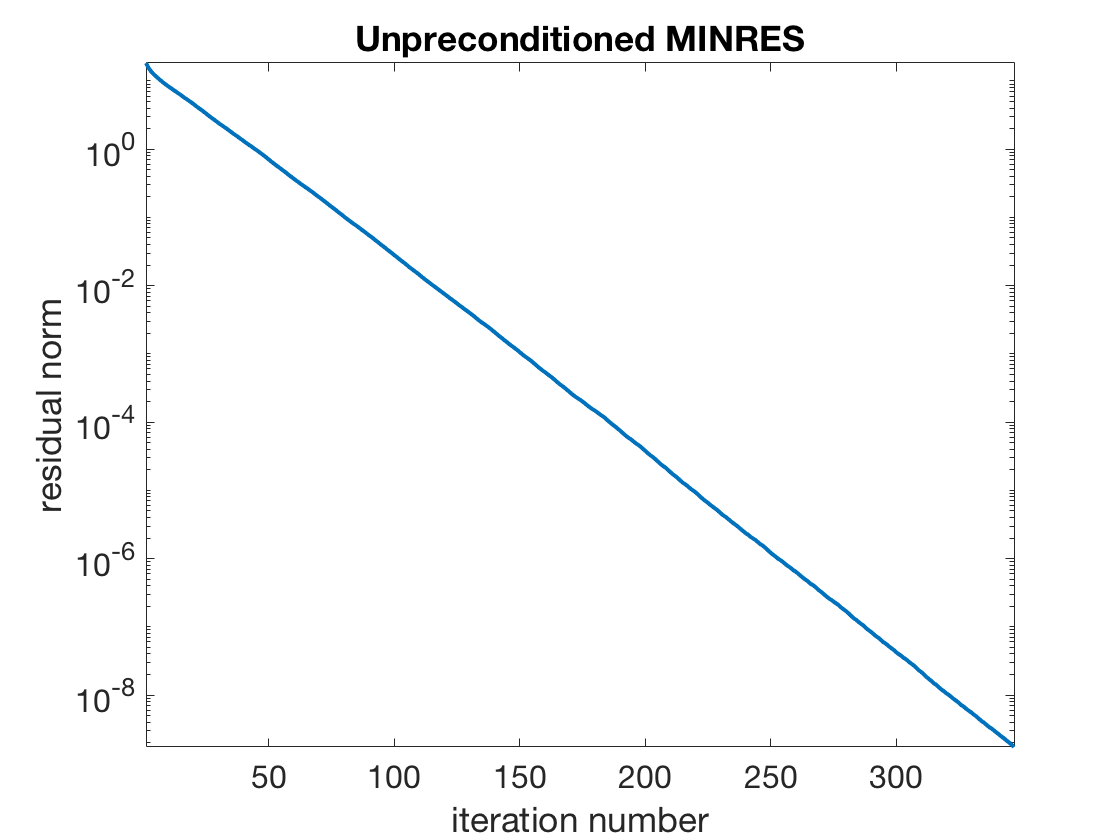

b = rand(1000,1);
[x,~,~,~,resid_plain] = minres(A,b,1e-10,400);
semilogy(resid_plain,'-')
xlabel('iteration number'), ylabel('residual norm')    % ignore this line
title('Unpreconditioned MINRES')   % ignore this line
axis tight    % ignore this line

For an SPD matrix we can use an incomplete Cholesky factorization. (It returns a lower triangular $\mathbf{L}=\mathbf{R}^T$ rather than an upper triangular $\mathbf{R}$.) However, it can fail, so here we add a shift to the eigenvalues of $\mathbf{A}$ to make it ``more positive.''

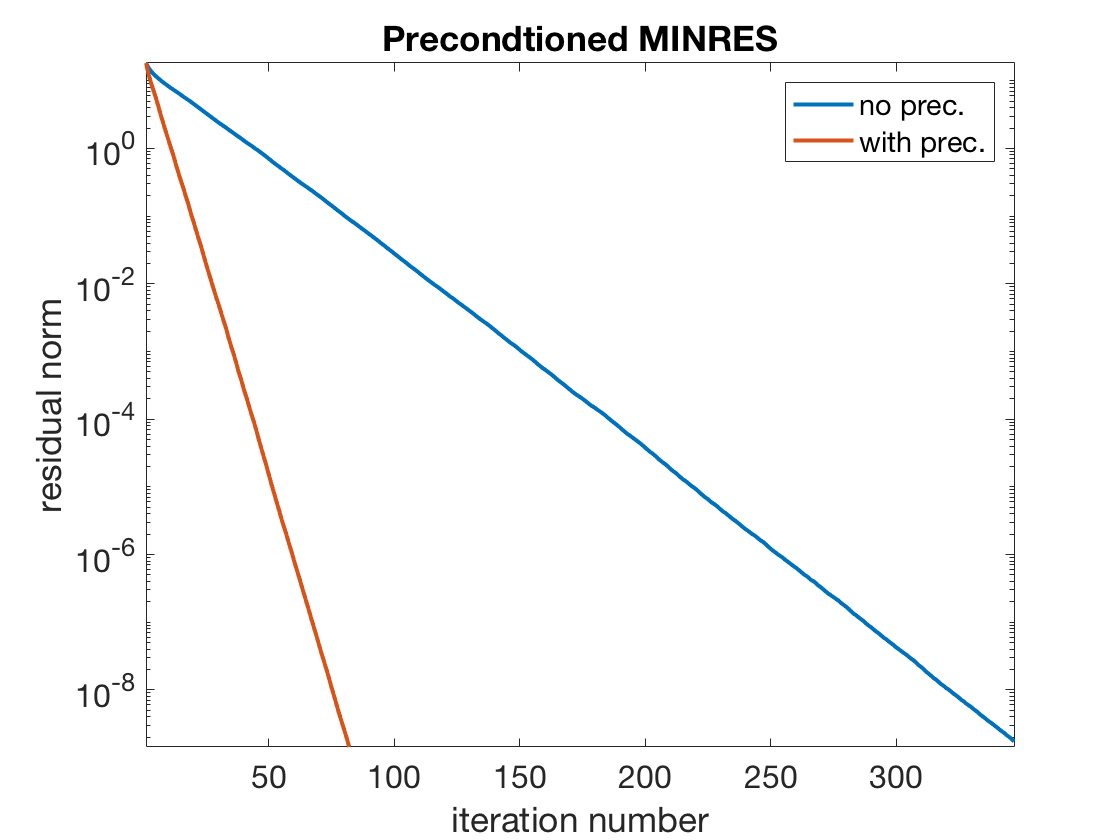

L = ichol(A+0.05*speye(1000));
[x,~,~,~,residPrec] = minres(A,b,1e-10,400,L,L');
hold on, semilogy(residPrec,'-')
title('Precondtioned MINRES')   % ignore this line
legend('no prec.','with prec.')    % ignore this line

The preconditioning was moderately successful. 